# Dimensionality Reduction and State-Space Systems: Forecasting the  Term Structure of Interest Rates Using the Diebold-Li Model

I have fit the Diebold-Li model of yield curve to a time series of monthly values of yield curves derived from the US Treasury yields ranging from 3 months to 30 years. Firstly, I have representated the Diebold-Li model in a parametric state-space form. Having estimated, simulated, smoothed and forecasted using the state-space models (SSM) as described in Diebold, Rudebusch, Aruoba (2006), I compared the results with those from the two-step method described in Diebold and Li (2006).  Lastly, I have simulated the yield curve using Monte Carlo and forecasted using the minimum mean square error (MMSE) technique embedded in the [SSM functionalities](https://www.mathworks.com/help/econ/ssm-class.html) from the Econometrics toolbox. 

## The Diebold-Li Model of the Yield Curve 

A variant of the Nelson-Siegel model, the Dynamic Nelson Siegel (DNS) or the Diebold-Li model is a reparameterization of the original equation. Given the time to maturity $\tau$, and date $t$ when the yield is observed, the yield $y_t(\tau)$from the Diebold-Li model is a function of four parameters: 


$$y_t(\tau) = L_t + S_t \left(\frac{1 - e^{-\lambda \tau}}{\lambda \tau} \right)
+ C_t \left(\frac{1 - e^{-\lambda \tau}}{\lambda \tau} - e^{-\lambda \tau} \right)$$
              
$$\left(1\right)$$


Here, $L_t$ is the level or the the long-term factor as it influences long-term bonds, $S_t$ is the slope or short-term factor, and $C_t$ is the curvature or the medium-term factor.  $\lambda$ determines the maturity at which the loading on the curvature is maximized, and governs the exponential decay rate of the model. 

After specifying the parametric form of an SSM, I have used MLE to estimate the model's parameters, caliberated the smoothed and filtered states by forward and backward recursion, respectively. Thereafter, Iacquired the optimal forecasts of the observed data and latent states, and employed Monte Carlo to simulate the trajectories of the yield curve and latent states.

In SSM, the state equation describes how the state evolves, while the measurement or observation equation describes how the measurable variables relate to the state variables. Given the state vector $x_t$ and observation vector $y_t$, the parametric form of the state-space model is expressed in the following linear state-space representation:


$$ x_t = A_t x_{t-1} + B_t u_t $$



$$ y_t = C_t x_t + D_t \epsilon_t $$


where $u_t$ and $\epsilon_t$ are uncorrelated, unit-variance white noise vector processes. In the aforementioned equations, the first  two equations are the *state equation* and * measurement equation, *respectively. The parameters of the model are matrices  $A_t$, $B_t$, $C_t$ and $D_t$ that correspond the *state transition*, *state disturbance loading*, *measurement sensitivity*, and *observation innovation* matrices, respectively.

## Diebold-Li Model in the State-Space System

The level, slope and curvature in the Diebold-Li model follow a first order vector autoregressive process or VAR(1), which has a state-space representation as follows: 


$$ \pmatrix {L_t - \mu_L \cr S_t - \mu_S \cr C_t - \mu_C}
= \pmatrix {a_{11} \ a_{12} \ a_{13} \cr a_{21} \ a_{22} \ a_{23}
\cr a_{31} \ a_{32} \ a_{33}}
\pmatrix{L_{t-1} - \mu_L \cr S_{t-1} - \mu_S \cr C_{t-1} - \mu_C}  + 
\pmatrix {\eta_t(L) \cr \eta_t(S) \cr \eta_t(C)}  $$


The corresponding measurement equation is: 


$$ \pmatrix{y_t(\tau_1) \cr y_t(\tau_2) \cr \vdots \cr
y_t(\tau_M)} =
\pmatrix{1 \ \frac{1 - e^{-\lambda \tau_1}}{\lambda \tau_1} \ 
\frac{1 - e^{-\lambda \tau_1}}{\lambda \tau_1} - e^{-\lambda \tau_1} \cr
1 \ \frac{1 - e^{-\lambda \tau_2}}{\lambda \tau_2} \ 
\frac{1 - e^{-\lambda \tau_2}}{\lambda \tau_2} - e^{-\lambda \tau_2} \cr
\vdots \cr
1 \ \frac{1 - e^{-\lambda \tau_M}}{\lambda \tau_M} \ 
\frac{1 - e^{-\lambda \tau_M}}{\lambda \tau_M} - e^{-\lambda \tau_M}}
\pmatrix {L_t \cr S_t \cr C_t} 
+ \pmatrix {\epsilon_t(\tau_1) \cr \epsilon_t(\tau_2) \cr \vdots \cr
\epsilon_t(\tau_M)} $$


In matrix notation, we can write the state-space system for the three-dimensional vector of the mean adjusted factors  $f_t$ and observed yields $y_t$: 


$$(f_t - \mu) = A(f_{t-1} - \mu) + \eta_t$$



$$y_t = \Lambda f_t + \epsilon_t$$


$\eta_t$ and $e_t$ are orthogonal to each other and follow white noise processes and we can write their distribution as: 


$$\pmatrix {\eta_t \cr \epsilon_t} \sim WN 
\pmatrix {\pmatrix {0 \cr 0} , \pmatrix
{Q \ 0 \cr 0 \ H}}$$



$$\left\lbrack \begin{array}{c}
Z_1 \\
Z_2 
\end{array}\right\rbrack \sim \textrm{WN}\left(\;\left\lbrack \begin{array}{c}
\mu_1 \\
\mu_2 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
\Sigma_{11}  & \Sigma_{12} \\
\Sigma_{21}  & \Sigma_{22} 
\end{array}\right\rbrack \right)\;$$



$$\left\lbrack \begin{array}{c}
\eta_t \\
\epsilon_t 
\end{array}\right\rbrack \sim \textrm{WN}\left(\;\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
\Sigma_{\eta }  & 0\\
0 & \Sigma_{\epsilon } 
\end{array}\right\rbrack \right)\;$$



$$E\left\lbrack a_{\textrm{ij}} \right\rbrack =\left\lbrace \begin{array}{ll}
0\ldotp 99,\textrm{if}\;i=j, & V\left\lbrack a_{\textrm{ij}} \right\rbrack =\gamma \frac{{\sigma_i }^2 }{{\sigma_j }^2 }\\
0\ldotp 01,\textrm{if}\;i\not= j & 
\end{array}\right.$$



$$E\left\lbrack \Omega_1^{\;\;\textrm{ij}} \right\rbrack =\left\lbrace \begin{array}{ll}
c_i \;,\textrm{if}\;i=j, & V\left\lbrack \Omega_1^{\;\;\textrm{ij}} \right\rbrack =\gamma \frac{{\sigma_i }^2 }{{\sigma_j }^2 }\\
0,\;\textrm{if}\;i\not= j & 
\end{array}\right.$$



$$\left(\left\lbrack \begin{array}{c}
X_t \\
\xi_t 
\end{array}\right\rbrack /Y_{t-1} \;\right)\sim N\left(\;\left\lbrack \begin{array}{c}
A{\hat{X} }_t \\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
{\Sigma^ˆ }_{X_t }  & {{\Sigma^ˆ }_{X_t } }^T \Lambda^T \\
{\Lambda \Sigma^ˆ }_{X_t }  & {\;\;\;\;\;\;\;\;\;\;\;\Lambda \Sigma^ˆ }_{X_t } \Lambda^T +\Sigma_{\epsilon } 
\end{array}\right\rbrack \right)\;$$


The factor disturbances  $\eta_t$ are correlated with each other, causing the covariance matrix $Q$ to be non-diagonal. In juxtaposition, the disturbances $e_t$ in the observation equation are uncorrelated, yielding a diagonal  covariance matrix $H$. 

The mean-adjusted factors describe the latent states:


$$x_t = f_t - \mu$$


The yields are demeaned or adjusted for intercept


$$y'_t = y_t - \Lambda\mu$$


Susbtituting these in the aforementioned equations, the state-space system of the Diebold-Li model can be characterized as: 


$$x_t = Ax_{t-1} + \eta_t$$



$$y'_t = y_t - \Lambda\mu = \Lambda x_t + e_t$$


The SSM functions in the Econometrics toolbox describes the state-space system as follows:


$$ x_t = A x_{t-1} + B u_t $$



$$ y_t = C x_t + D \epsilon_t $$


The state transition matrix $A$ in the SSM functionality matches with that of the matrix $A$ in the Diebold-Li formulation, while $\Lambda$ is equivalent to the state measurement sensitivity matrix $C$ in the SSM formulation.

Unlike the straightforward relationship of state transition and measurement sensitivity matrices with those in the Diebold-Li state-space system, the disturbances have a more sophisticated relationship, leading to a subtle parameterization of the $B$ and $D$ matrices. We observe that that the disturbances of the Diebold-Li state space system equate with those in the SSM functionality. 


$$$\eta_t = Bu_t$$



$$e_t = D\epsilon_t$$


As the disturbances $u_t$ and $\epsilon_t$ are unit-variance, uncorrelated, white noise vector processes, their covariance matrices are identity matrices. Therefore, we relate the parameters of the SSM function ot the covariance of the Diebold-Li model such that:


$$Q = BB'$$



$$H = DD'$$


Representing the Diebold-Li model in the state-space system, I have created the SSM implicitely by enumerating  a parameter mapping function whereby a vector of input parameters is mapped to parameters$A$, $B$, $C$, and $D$ of the model. I have employed a mapping function as the three latent factors in the Diebold-Li model are demeaned, which forms a common regression component. Additionally, the mapping function ensures that the $Q = BB'$ is symmetric, the covariance matrix $H = DD'$ is diagonal. Finally, the mapping function estimates the decay parameter $\lambda$. Implicitely, the mapping function specifies the model. This is advantageous as we can estimate convoluted models and impose multiple constraints on the parameters. 

Moreover, I have demeaned the yields $y_t$ as the SSM functions such as `filter`,  `smooth`, `forecast`, and `simulate`, assume that observations are already manually demeaned. While estimating, a parameter mapping function deflates the yields observed. The upside is that it maintains the three-dimensionality of the latent factors in the state vector. Nonetheless, the downside is that I have to separately deflate and subsequently inflate the yields to offset the adjustment from estimating on the demeaned yields. 

## The Yield Curve Data

I have aggregated the monthly data on the treasury yields of various maturities, ranging from 3 month to 30 years from [FRED](https://fred.stlouisfed.org/). Depicting a snapshot of the current yield levels in the market, each of the ten series has both a cross-sectional and a temporal dimension. 

score =     3.6445    1.4172   -0.0164    0.0355   -0.0126    0.0789    0.0092   -0.0125   -0.0231   -0.0143
    4.4332    1.8032   -0.0508    0.0471   -0.0388    0.0345   -0.0272   -0.0296   -0.0103   -0.0207
    4.4024    1.9380   -0.1615   -0.0237   -0.0087    0.0338   -0.0238    0.0054   -0.0285   -0.0440
    4.0180    1.7597   -0.0877   -0.0298    0.0158    0.0004   -0.0449   -0.0311   -0.0402   -0.0280
    5.6163    1.9656   -0.1863   -0.0073    0.0431    0.0006    0.0218   -0.0057   -0.0206   -0.0115
    7.0827    2.4914   -0.5446   -0.0647   -0.0176   -0.0590   -0.0134    0.0225    0.0430    0.0236
    8.3686    2.2893   -0.6293   -0.1596   -0.0483   -0.0892   -0.0103    0.0421    0.0016    0.0339
    9.0822    2.0705   -0.4930   -0.2202   -0.0656   -0.0780    0.0362    0.0080   -0.0269    0.0210
    9.4717    2.3287   -0.6343   -0.2947   -0.0494   -0.0862    0.0150    0.0492    0.0173   -0.0051
    8.9989    1.9298   -0.4652   -0.1895   -0.0133   -0.1137    0.0023    0.0002   

explained =    94.2829
    5.2684
    0.3561
    0.0477
    0.0186
    0.0153
    0.0038
    0.0033
    0.0028
    0.0010


avg =     2.3889    2.5141    2.6354    2.8809    3.0744    3.4426    3.7441    3.9800    4.4922    4.5419


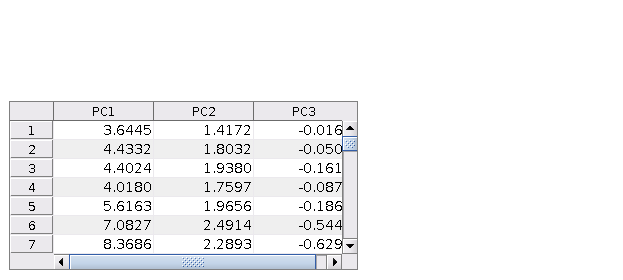

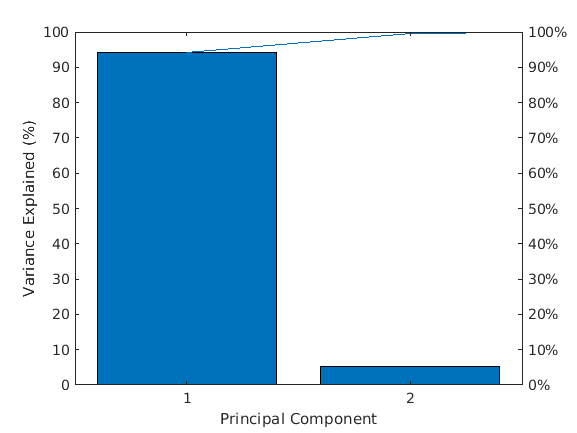

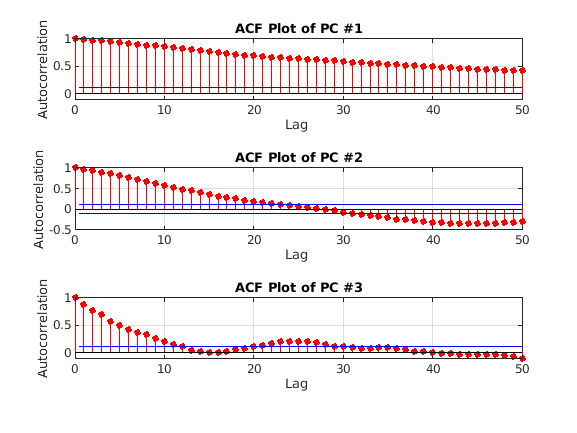

% has data from October 31, 1993 to August 30, 2020 collected from FRED
% no missing values
tres = readtable("data_df.csv");

% extract the "Dates" column and store it as "dates" table
dates = table2array(tres(:, 'Date')); 

% extract column names of table "tres"
tres.Properties.VariableNames;

% removes the "Date" column
tresc= removevars(tres,{'Date'});
data = table2array(tresc);

% DataTable: has columns' names of yields of varying ttm
% and row names for each date

% yields of 10 term to maturity (TTM) in months
ttm =[3; 6; 12; 24; 36; 60; 84; 120; 240; 360];

% yields = dataset on 10 different maturities for in-sample modeling
yields = data(1:end,:);      % in-sample yields for estimation

## Two-Step Diebold-Li Model with Fixed $\lambda$

Finding the ex-ante value of the latent factors is tantamount to finding the ex-ante values of the yield curve as it is a function of the factors. Then, I have constructed the Diebold-Li model with the explanatory variables as factor forecasts. The two-step approach of fitting the Diebold and Li model and estimating the parameters of their yield curve is:

- Firstly, I have kept $\lambda$ fixed and estimated the level, slope, and curvature parameters for each of the daily values of the yield curve. We can  consider the regression coefficients from OLS as the as the three factors. Repeating this process for all observed yield curves yields a three-dimensional matrix of estimates of the three latent factors. Keeping $\lambda$ fixed simplifies the estimation method from non-linear least squares to OLS, which creates a static Nelson Siegel model at each month.

- Secondly, I have fitted $\textrm{VAR}\left(1\right)$ to the time series of factors derived in the first step.

In the Nelson-Siegel model, $\lambda_t$ determines the time to maturity at which the loadings on the curvature, or the medium-term factor are maximized. These are usually yields that mature in 24 to 36 months.  Dielbold and Li (2005) set $\lambda_t =0\ldotp 0609\;$ for all $t\ldotp$ This is the value at which the loading on the curvature (medium-term factor) is maximized occurs at 30 months. Below, I have shown the first-step in the Diebold-Li model, and accumulated the coefficients (factor loadings) and the residuals from the OLS model. The factor loadings on $\beta_1 ,\beta_2$ and $\beta_3$ govern the level, slope and curvature, respectively, of the yield curve. Then, I plotted the factor loadings in one graphs. 

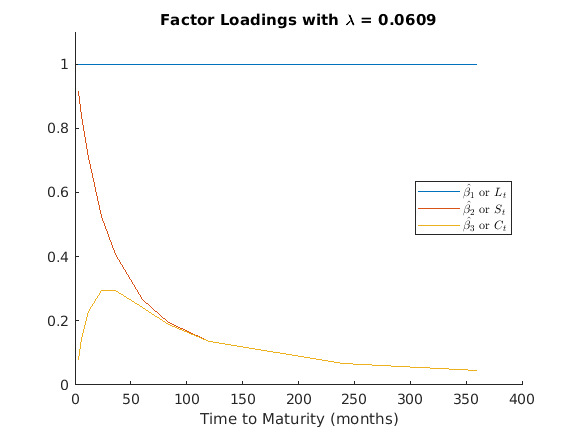

lambda0 = 0.0609;
% X is a 10 by 3 matrix: as there is data on 10 different yields and 3 beta
% factors
X = [ones(size(ttm)) (1-exp(-lambda0*ttm))./(lambda0*ttm) ...
    ((1-exp(-lambda0*ttm))./(lambda0*ttm)-exp(-lambda0*ttm))];


% size(yields,1): queries the length of the 1st dim of 'yields" : 324
% beta = zeros(324, 3)
% stores the beta
beta = zeros(size(yields,1),3);

% numel : returns the number of elements in array "ttm" : 10
% resid = zeros(324, 10)
% stores the resid from the OLS model
resid = zeros(size(yields,1),numel(ttm));

% fix lambda and compute the 3 beta params for each monthly observation of the
% yield curve by OLS
% the beta coefficients from the OLS regression are equivalent to the 3
% factors: level, slope, and curvature
% collect the 3D time-series of the betas (estimated factors) by fitting
% the OLS model on each yield curve observed
% store the betas (regression coefficients) and resid

for i = 1:size(yields,1) 
    OLSmod = fitlm(X, yields(i,:)', 'Intercept', false);
    beta(i,:) = OLSmod.Coefficients.Estimate';
    
    % raw residuals (observed - fitted values) from the OLS model 
    resid(i,:) = OLSmod.Residuals.Raw'; 
end


% Plot the factor loadings
figure
hold on
plot(ttm,X)
title('Factor Loadings with \lambda = 0.0609')
xlabel('Time to Maturity (months)')
ylim([0 1.1])
legend({'$\hat{\beta_1}$ or $L_t$';'$\hat{\beta_2}$ or $S_t$'; ['$\hat{\beta_3}$ ' ...
    'or $C_t$']},'Interpreter', 'latex','location','east')
hold off

$\beta_1$ is a flat line parallel to the maturity axis, representing the constant $L_t$ in the Diebold-Li equation $\left(1\right)\ldotp$ The loadings on $\beta_2$ or $S_t$ is a function $\frac{1-e^{\lambda \tau } }{\lambda \tau }$ , that starts at 1 approximately but monotonically decays to 0; therefore, it is a convex-shaped curve. Finally, the loadings on $\beta_3$ or $C_t$ is a function $\frac{1-e^{\lambda \tau } }{\lambda \tau }-e^{-\lambda \tau }$ that starts at 0 and gradually converges to 0, affecting the medium-term yields. $\lambda_t$ governs the pace of exponential decay wherein small values of $\lambda_t$ slows the decay and better fits the curve at longer term maturities. This contrasts with large values of $\lambda_t$ which fastens the rate of recay and better fits shorter-term maturities.  Now, I have compared the path of the level, slope and curvature with their corresponding factor loadings from the first step (OLS regresson) in the Diebold-Li model. The 10-year Treasury yield is a measure of level. The slope or the yield spread is the difference between the 3-month and 10-year Treasury yield. Lastly, the curvature is measured as $2\times 2y-10y-3\textrm{mo}\ldotp$

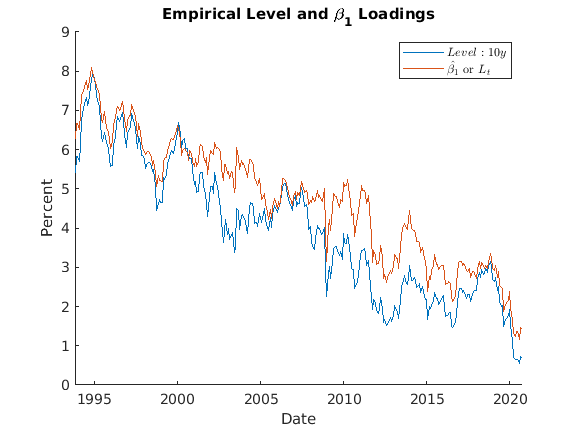

% actual level, slope and curvature from the dataset
% measure of level: L_t
tres_level = tres{:, 'tres10y'};

% measure of slope S_t = yield spread
tres_slope = tres{:, 'tres3mo'} - tres{:, 'tres10y'};

% measure of curvature C_t
tres_curvature = 2*tres{:, 'tres2y'} - tres{:, 'tres10y'} - tres{:, 'tres3mo'};

% stack them together in a matrix
compare_mat = [tres_level tres_slope tres_curvature beta];

% Convert the matrix into a table with variable names
compare_tab = array2table(compare_mat,...
    'VariableNames',{'level','slope','curvature', 'beta1', 'beta2', 'beta3'});

% convert the string of dates into datetime format
dates_dt = array2table(datetime(dates,'InputFormat','yyyy-MM-dd'), ...
    'VariableNames',{'Date'});

% stack the datetime dates with the level, slope and curvature in a table
compare_dt = [dates_dt, compare_tab];


% In each separate graph, plot the level, slope and curvature 
% alsongside its corresponding factor loadings 

figure
hold on
plot(dates, compare_mat(:,[1,4]))
title('Empirical Level and \beta_1 Loadings')
xlabel('Date')
ylabel('Percent')

legend({'$Level: 10y$';'$\hat{\beta_1}$ or $L_t$'},'Interpreter', 'latex', ...
    'location','northeast')
hold off

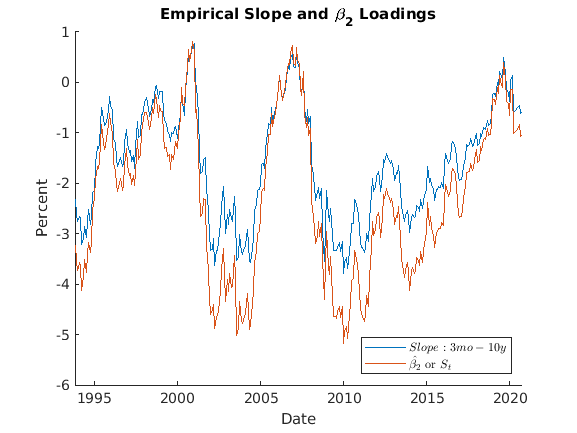

figure
hold on

plot(dates, compare_mat(:,[2,5]))
title('Empirical Slope and \beta_2 Loadings')
xlabel('Date')
ylabel('Percent')
legend({'$Slope: 3mo-10y$';'$\hat{\beta_2}$ or $S_t$'},'Interpreter', 'latex', ...
    'location','southeast')
hold off

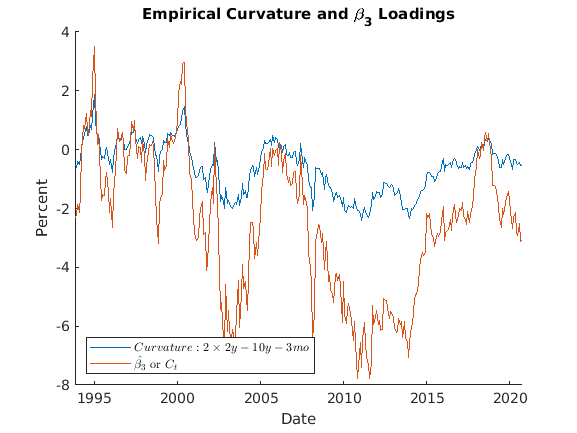

figure
hold on

plot(dates, compare_mat(:,[3,6]))
title('Empirical Curvature and \beta_3 Loadings')
xlabel('Date')
ylabel('Percent')
legend({'$Curvature: 2\times2y-10y-3mo$';'$\hat{\beta_3}$ or $C_t$'},'Interpreter', ...
    'latex','location','southwest')
hold off

The empirical level, slope and curvature factors, alonside their corresponding factor loadings closely follow each other, as also reflected by the high positive correlation with each other :


$$\rho \left(10y\;,\textrm{level}\;\right)=0\ldotp 9615,:\rho \left(3\textrm{mo}-10y\;,\textrm{slope}\;\right)=0\ldotp 9939,\rho \left(2\times 2y-10y,\textrm{curvature}\;\right)=0\ldotp 9781\ldotp \;$$


corr_compare = corrcoef(compare_mat);
rowNames = {'10y','3mo-10y','2*2y-10y-3mo', 'beta 1', 'beta 2', 'beta 3'};
colNames = {'level','slope','curvature', 'beta 1', 'beta 2', 'beta 3'};
corr_compare_tab = array2table(corr_compare,'RowNames',rowNames, ...
    'VariableNames',colNames)

corr_compare_tab = 6×6 table
                     level       slope      curvature     beta 1      beta 2     beta 3 
                    ________    ________    _________    ________    ________    _______

    10y                    1    0.094987     0.56165      0.96154     0.14046    0.59595
    3mo-10y         0.094987           1     0.57853     -0.13375     0.99394    0.53793
    2*2y-10y-3mo     0.56165     0.57853           1      0.33333     0.64126    0.97806
    beta 1           0.96154    -0.13375     0.33333            1    -0.10022    0.36728
    beta 2           0.14046     0.99394     0.64126     -0.10022           1    0.60333
    beta 3           0.59595     0.53793 

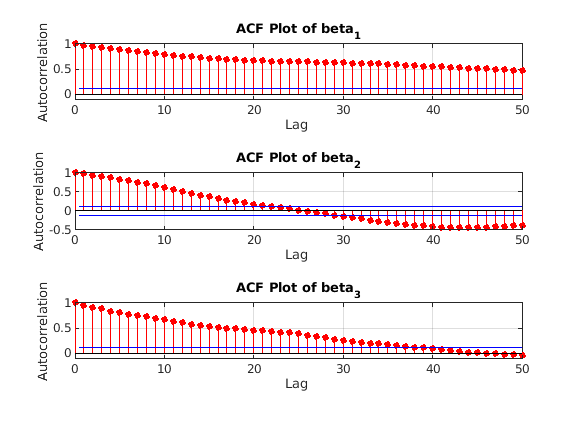

figure
hold on % retains current plot while adding new plots
for i=1:3
    subplot(3,1,i)
    autocorr(beta(:,i), 50)
    caption = sprintf('ACF Plot of beta_%d', i);
    title(caption, 'FontSize', 15);
    
    % label the x-axis and add extra space between two plots
    xlabel("Lag " + newline + "   ")
    ylabel("Autocorrelation")
  
end
hold off  

% Summary stats of the latent variables from the Diebold-Li model (DNS)


tab_beta=table();
tab_beta.Min=min(beta)';
tab_beta.Mean=mean(beta)'; 
tab_beta.Max=max(beta)';
tab_beta.Std_dev=std(beta)';
tab_beta.Properties.RowNames = {'beta 1', 'beta 2', 'beta 3'};

disp_sumstat_beta = {"Summary Statistics of the Latent Variables from DNS:";...
    "----------------------------------";...
    tab_beta};
cellfun(@disp,disp_sumstat_beta)

Summary Statistics of the Latent Variables from DNS:
----------------------------------
                Min       Mean        Max      Std_dev
              _______    _______    _______    _______

    beta 1     1.1602     4.7137     8.1034    1.5517 
    beta 2    -5.1804    -2.2325    0.81551    1.5339 
    beta 3    -7.7825     -2.491     3.5225    2.4178 



The descriptive statistics indicates that the curvature factor is most volatile, followed by the level and slope factors, respectively. After fitting the three-dimensional data of factors, I have fit a first$-$order VAR model  on this estimated time series of factors. As the  SSM equation works with factors adjusted for mean, I incorporated an additive constant  to the $\textrm{VAR}\left(1\right)$ model. 

% fit a VAR(1) model in the 3D time series of the estimated factors "beta"
% for each of the 324 observations obtained

% "VARmod" stores the estimated parameter values acquired when we fit VAR(1)
% MLE estimates the parameters

VARmod = estimate(varm(3,1), beta);

% Create a  Bayesian VAR model under conjugate priors
% It specifies the prior distribution of the AR coefficient matrices, model constant vector, 
% and innovations covariance matrix. 
% bayesvarm: displays a summary of the prior distributions 
% numseries = 3; numlags = 1
BVARmod = estimate(bayesvarm(3,1, 'ModelType','conjugate' ), beta);

Bayesian VAR under conjugate priors
Effective Sample Size:          323
Number of equations:            3
Number of estimated Parameters: 12
             |   Mean     Std  
-------------------------------
 Constant(1) |  0.0957  0.0604 
 Constant(2) |  0.1009  0.0739 
 Constant(3) | -0.2767  0.1506 
 AR{1}(1,1)  |  0.9785  0.0115 
 AR{1}(2,1)  | -0.0325  0.0141 
 AR{1}(3,1)  |  0.0382  0.0287 
 AR{1}(1,2)  |  0.0004  0.0134 
 AR{1}(2,2)  |  0.8951  0.0164 
 AR{1}(3,2)  |  0.0326  0.0335 
 AR{1}(1,3)  |  0.0033  0.0092 
 AR{1}(2,3)  |  0.0704  0.0112 
 AR{1}(3,3)  |  0.9330  0.0228 
   Innovations Covariance Matrix   
    |    Y1        Y2        Y3    
-----------------------------------
 Y1 |  0.0755   -0.0595    0.0204  
    | (0.0059)  (0.0060)  (0.0104) 
 Y2 | -0.0595    0.1131   -0.0458  
    | (0.0060)  (0.0088)  (0.0129) 
 Y3 |  0.0204   -0.0458    0.4698  
    | (0.0104)  (0.0129)  (0.0366) 



% Display summary statistics from the estimation.
varsum = summarize(VARmod);
bvarsum = summarize(BVARmod);

             |   Mean     Std  
-------------------------------
 Constant(1) |  0.0957  0.0604 
 Constant(2) |  0.1009  0.0739 
 Constant(3) | -0.2767  0.1506 
 AR{1}(1,1)  |  0.9785  0.0115 
 AR{1}(2,1)  | -0.0325  0.0141 
 AR{1}(3,1)  |  0.0382  0.0287 
 AR{1}(1,2)  |  0.0004  0.0134 
 AR{1}(2,2)  |  0.8951  0.0164 
 AR{1}(3,2)  |  0.0326  0.0335 
 AR{1}(1,3)  |  0.0033  0.0092 
 AR{1}(2,3)  |  0.0704  0.0112 
 AR{1}(3,3)  |  0.9330  0.0228 
   Innovations Covariance Matrix   
    |    Y1        Y2        Y3    
-----------------------------------
 Y1 |  0.0755   -0.0595    0.0204  
    | (0.0059)  (0.0060)  (0.0104) 
 Y2 | -0.0595    0.1131   -0.0458  
    | (0.0060)  (0.0088)  (0.0129) 
 Y3 |  0.0204   -0.0458    0.4698  
    | (0.0104)  (0.0129)  (0.0366) 



Acoef = VARmod.AR{1}

Acoef =     0.9961    0.0093   -0.0043
   -0.0274    0.9130    0.0631
    0.0334    0.0246    0.9418


The $\left(3\times 3\right)$ matrix A is:


$$A_1^{2-\textrm{step}} =\left\lbrack \begin{array}{ccc}
0\ldotp 9961 & 0\ldotp 0093 & -0\ldotp 0043\\
-0\ldotp 0274 & 0\ldotp 913 & 0\ldotp 0631\\
0\ldotp 0334 & 0\ldotp 0246 & 0\ldotp 9418
\end{array}\right\rbrack$$


% Extract the variance covariance matrix of the innovations of VAR(1)
sigma_eta = VARmod.Covariance

sigma_eta =     0.0598   -0.0604    0.0199
   -0.0604    0.1027   -0.0495
    0.0199   -0.0495    0.4678


The variance-covariance matrix of the innovations of VAR(1) are:


$$\Sigma_{\eta }^{2-\textrm{step}} =\left\lbrack \begin{array}{ccc}
0\ldotp 0598 & -0\ldotp 0604 & 0\ldotp 0199\\
-0\ldotp 0604 & 0\ldotp 1027 & -0\ldotp 0495\\
0\ldotp 0199 & -0\ldotp 0495 & 0\ldotp 4678
\end{array}\right\rbrack$$


Then I have forecasted the time series of the latent factors:

beta_table = array2table(beta); 
beta_date = table2timetable(beta_table,'RowTimes',dates);

numperiods = 12;
fct_date = dateshift(beta_date.Time(end),'end','month',1:numperiods);
[Forecast,ForecastMSE] = forecast(VARmod,numperiods,beta(end-3:end,:));

Extract the main diagonal elements from the matrices in each cell of `ForecastMSE`. Apply the square root of the result to obtain standard errors.

extractMSE = @(x)diag(x)';
MSE = cellfun(extractMSE,ForecastMSE,'UniformOutput',false);
SE = sqrt(cell2mat(MSE));

The 95% forecast intervals for each of the latent factors are estimated as:

mdl = varm(3,1)

mdl =   varm with properties:

     Description: "3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [3×1 vector of NaNs]
              AR: {3×3 matrix of NaNs} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix of NaNs]

ForecastFI = zeros(numperiods,mdl.NumSeries,2);

ForecastFI(:,:,1) = Forecast - 2*SE;
ForecastFI(:,:,2) = Forecast + 2*SE;


Finally, I have plotted the individual forecasts for 1 year ahead alongside the 95 % forecast intervals. 

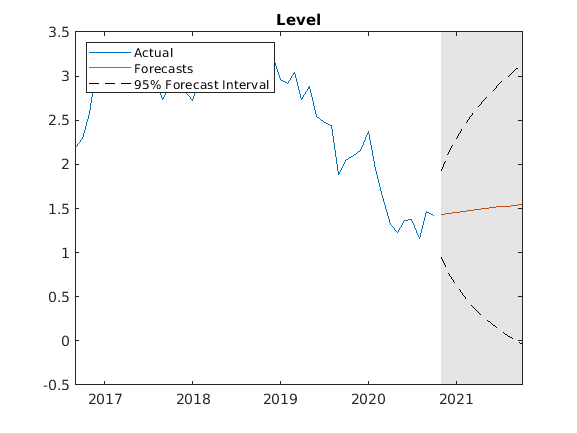

figure;
h1 = plot(beta_date.Time((end-49):end),beta((end-49):end,1));
hold on;
h2 = plot(fct_date,Forecast(:,1));
h3 = plot(fct_date,ForecastFI(:,1,1),'k--');
plot(fct_date,ForecastFI(:,1,2),'k--');
title('Level');
h = gca;
fill([fct_date(1) h.XLim([2 2]) fct_date(1)],h.YLim([1 1 2 2]),'k',...
    'FaceAlpha',0.1,'EdgeColor','none');
legend([h1 h2 h3],'Actual','Forecasts','95% Forecast Interval',...
    'Location','northwest')
hold off;

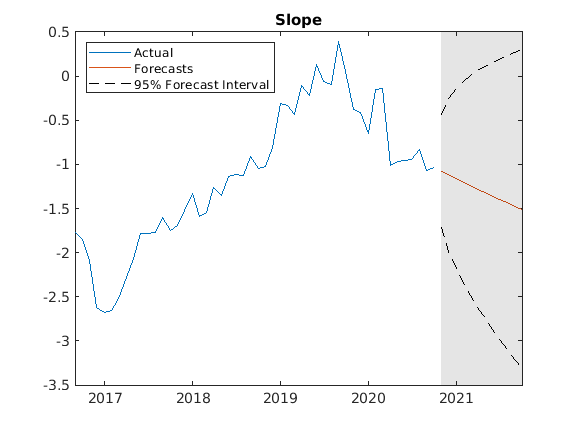


figure;
h1 = plot(beta_date.Time((end-49):end),beta((end-49):end,2));
hold on;
h2 = plot(fct_date,Forecast(:,2));
h3 = plot(fct_date,ForecastFI(:,2,1),'k--');
plot(fct_date,ForecastFI(:,2,2),'k--');
title('Slope');
h = gca;
fill([fct_date(1) h.XLim([2 2]) fct_date(1)],h.YLim([1 1 2 2]),'k',...
    'FaceAlpha',0.1,'EdgeColor','none');
legend([h1 h2 h3],'Actual','Forecasts','95% Forecast Interval',...
    'Location','northwest')
hold off;

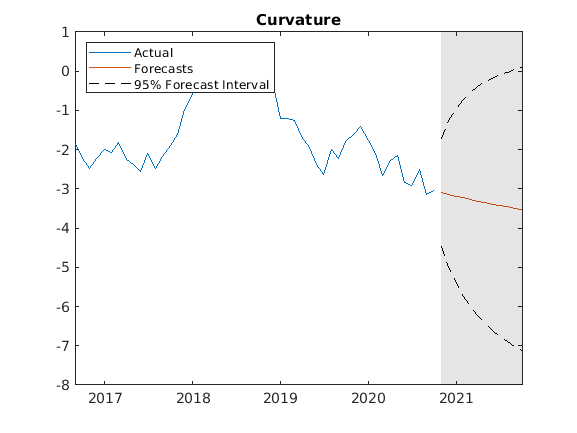



figure;
h1 = plot(beta_date.Time((end-49):end),beta((end-49):end,3));
hold on;
h2 = plot(fct_date,Forecast(:,3));
h3 = plot(fct_date,ForecastFI(:,3,1),'k--');
plot(fct_date,ForecastFI(:,3,2),'k--');
title('Curvature');
h = gca;
fill([fct_date(1) h.XLim([2 2]) fct_date(1)],h.YLim([1 1 2 2]),'k',...
    'FaceAlpha',0.1,'EdgeColor','none');
legend([h1 h2 h3],'Actual','Forecasts','95% Forecast Interval',...
    'Location','northwest')
hold off;

## One-Step Kalman Filter  with $\lambda$ as a Random Variable

By specifying a parameter mapping function, I have estimated the Diebold-Li model  implicity. This mapping function maps a parameter vector to SSM model parameters, deflates the observations to account for the means of each factor, and imposes constraints on the covariance matrices. 

% create an SSM model
% pass the parameter mapping function "Example_DieboldLi" to the "ssm"
% function
% the input vector "params" calls the mapping function 
% other input arguments to mapping function: information on yields and time
% to maturity
% link to the mapping function: 
% https://www.mathworks.com/matlabcentral/fileexchange/47479-data_dieboldli-zip


model = ssm(@(params)dns(params,yields,ttm));

Then, the Kalman filter in the state-space model helps to output maximum likelihood estimates, optimal smoothed and filtered estimates of the latent factors.  However, the Kalman filter can be very sensitive to the initial values of the parameters if we use it to compute the MLE of the SSM model. So, I have initialized the estimation by inputting the results from  the Diebold-Li two-step method to acquire the intial transition matrix.  

Encoded in a column vector are the initial values passed in the SSM `estimate.`While the  matrix $A$ of the SSM model is a  3-by-3 AR coefficient matrix of the $VAR(1)$ model, it is stacked in a column vector of 9 elements.  Likewise,  the matrix $B$ of the is a 3-by-3 matrix  such that we can decompose the postive-definite symmetric matrix $Q$ into a product of two matrices: $B$ and its transpose $:Q = BB'$. Herein, $B$ is the lower Cholesky factor of $Q$. To ensure that the off-diagonal elements of the matrix $Q$ is non-diagonal i.e. the elements are correlated with each other, I have allocated six elements of the lower Cholesky factor $B$ as a column vector of inital parameter values.  Then, I initialized the elements of the initial parameters' vector by taking a square root of the variance of the estimated innovations from the VAR(1) model. Thus, I have assumed diagonality in the covariance matrix $Q$. As before, I have arranged the initial parameter vector in a manner such that the elements of $B$ along and below the diagonal are stacked as a column vector. 

Just as with matrix $B$, I have constrained the matrix $D$ to be diagonal. This is because the covariance matrix $H$ in the Diebold-Li model is also diagonal, implying that $H = DD'$. Hence,  the vector of initial parameters is the square root of the diagonal elements of the sample covariance matrix of innovations from $VAR(1).$

Therefore, the elements of the initial parameter vector associated with $D$ are set to the square root of the diagonal elements of the sample covariance matrix of the resid of the $VAR(1)$ model, "one such element for each of the 10 time to maturity of the yields are arranged column-wise.

Unlike other aforementioned matrices in the state-space system, the matrix  $C$ is indirectly estimated. Computed internally by the mapping function, it is a parametarized function of the estimated decay rate parameter $\lambda$. $\lambda$ is initialized to 0.0609 as Diebold, Li and Rudebusch (2006) did.  Lastly, I've set the sample average of the three OLS regression coefficients (in the first step) as the vector of initial latent factor parameters. 

In total, the numerical optimization estimates 29 free parameters. These are as as follows:

9  parameters from the 3-by-3 matrix $A;$ 

3 parameters from the 3-by-1 vector of means $\mu ;$ 

1 parameter from the measurement matrix $\Lambda ,$ which is the exponential decay rate $\lambda ;$ 

6 parameters from the transition disturbance matrix $Q:$ for each of the three latent factors, I computed the error variance$\;:\sigma_l^2 ,\sigma_s^2 ,\sigma_c^2 \;;$ and three covariance terms $:\sigma_{\textrm{lc}} ,\sigma_{\textrm{ls}} ,\sigma_{\textrm{sc}} \;;$

10 parameters from the measurement disturbance covariance matrix $H:$ for each of the ten yields, I computed the error variances as above. 

% Get the VAR(1) matrix (stored as a cell array)
% A0: 3-by-3 coefficient matrix at lag 1
A0 = VARmod.AR{1}; 
A0_bvar = BVARmod.AR{1};

% Columnwise stacking: stacked the above 3-by-3 coefficient matrix into a 
% 9-by-1 column vector
A0 = A0(:);  
A0_bvar = A0_bvar(:);

% Extract the variance covariance matrix of the innovations of VAR(1)
Q0 = VARmod.Covariance

Q0 =     0.0598   -0.0604    0.0199
   -0.0604    0.1027   -0.0495
    0.0199   -0.0495    0.4678


Q0_bvar = BVARmod.Covariance

Q0_bvar =     0.0755   -0.0595    0.0204
   -0.0595    0.1131   -0.0458
    0.0204   -0.0458    0.4698



% B: take the square root of the diagonal elements of Q and other elements
% other elements of Q are 0

B0 = [sqrt(Q0(1,1)); 0; 0; sqrt(Q0(2,2)); 0; sqrt(Q0(3,3))];
B0_bvar = [sqrt(Q0_bvar(1,1)); 0; 0; sqrt(Q0_bvar(2,2)); 0; sqrt(Q0_bvar(3,3))];

% H0: 10-by-10 covariance matrix of the residuals from the OLS model
H0 = cov(resid); 

% diag(H0): stores the elements of the main diagonal of the 10-by-10
% matrix D0 as a column vector: 
% it is the square root of the diagonal elements of 
D0 = sqrt(diag(H0)); 

% Average of the 3 beta coefficients
mu0 = mean(beta)'

mu0 =     4.7137
   -2.2325
   -2.4910



% each of the 4 params is a vector, respectively
% param0 stack these 4 vectors into a column vector one below the other
% (vectorize)
% param0: the initial parameter column vector.
% lamda is set to a pre-specified value
% lamda is stored in the last element of param0
param0 = [A0; B0; D0; mu0; lambda0];

After caliberating the initial values, I have established the optimization parameters and estimated the model via the Kalman filter. The Kalman filter outputs the maximum likelihood estimates, optimal filtered and smoothed estimates of the 29 free parameters. As the covariance matrix $H = DD'$ is diagonal, i.e. the observation innovations are uncorrelated, I have treated the multivariate series as a univariate series. This hastens the estimation's runtime performance, and enhances numerical stability. 

____________________________________________________________
   Diagnostic Information

Number of variables: 29

Functions 
Objective:                            @(c)-fML(c,Mdl,Y,Predictors,unitFlag,sqrtFlag,mexFlag,mexTvFlag,tol,ind,switchTime,precaution)
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)
 

Algorithm selected
   quasi-newton


____________________________________________________________
   End diagnostic information


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0          30         -688.369                      9.83e+04


     1         120         -1467.71    1.01772e-07       4.87e+04  


     2         150         -1666.84              1        2.1e+04  


     3         180          -1710.9              1       6.67e+03  


     4         210         -1747.49              1        6.1e+03  


     5         240         -1890.78              1       1.46e+04  


     6         270         -1977.46              1       1.29e+04  


     7         300         -2029.07              1       6.85e+03  


     8         330         -2043.97              1       1.91e+03  


     9         360         -2046.81              1       1.09e+03  


    10         390         -2048.34              1       1.21e+03  


    11         420         -2052.24              1       2.46e+03  


    12         450          -2060.3              1       3.58e+03  


    13         480         -2075.18              1       3.83e+03  


    14         510         -2088.81              1       2.05e+03  


    15         540         -2097.06              1            982  


    16         570         -2103.63              1       2.04e+03  


    17         600         -2104.51              1            931  


    18         630          -2105.8              1            657  


    19         660         -2108.91              1       3.79e+03  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
    20         690         -2113.87              1       6.91e+03  


    21         720         -2124.87              1       1.04e+04  


    22         750         -2140.06              1       1.02e+04  


    23         780         -2148.83              1       5.39e+03  


    24         810            -2152              1       2.05e+03  


    25         840         -2153.45              1            868  


    26         870         -2154.11              1       1.44e+03  


    27         900         -2156.43              1       3.25e+03  


    28         930         -2160.76              1       5.12e+03  


    29         960         -2168.56              1       6.56e+03  


    30         990         -2175.61              1       5.33e+03  


    31        1020         -2180.49              1       1.66e+03  


    32        1050         -2181.64              1       1.04e+03  


    33        1080         -2182.31              1        1.1e+03  


    34        1110         -2185.31              1       3.17e+03  


    35        1140         -2190.62              1       4.87e+03  


    36        1170         -2200.12              1       6.29e+03  


    37        1200         -2207.92              1        4.2e+03  


    38        1230         -2210.47              1       1.52e+03  


    39        1260          -2211.2              1            532  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
    40        1290          -2211.5              1            641  


    41        1320         -2212.47              1            745  


    42        1350         -2214.96              1            815  


    43        1380         -2220.41              1            873  


    44        1410         -2229.61              1            917  


    45        1440         -2234.69              1            857  


    46        1470         -2235.89              1            821  


    47        1500         -2236.85              1            700  


    48        1530         -2237.28              1            636  


    49        1560         -2238.44              1            494  


    50        1590         -2240.47              1            514  


    51        1620         -2243.99              1            539  


    52        1650         -2248.16              1            606  


    53        1680          -2250.4              1            633  


    54        1710         -2250.71              1            418  


    55        1740         -2250.82              1            375  


    56        1770         -2251.18              1            296  


    57        1800         -2251.75              1            287  


    58        1830         -2252.56              1            263  


    59        1860         -2253.05              1            172  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
    60        1890         -2253.17              1            161  


    61        1920          -2253.2              1            155  


    62        1950         -2253.25              1            148  


    63        1980         -2253.35              1            150  


    64        2010         -2253.61              1            181  


    65        2040         -2254.15              1            260  


    66        2070         -2255.08              1            269  


    67        2100         -2256.02              1            163  


    68        2130         -2256.38              1            125  


    69        2160         -2256.43              1            124  


    70        2190         -2256.46              1            122  


    71        2220         -2256.53              1            114  


    72        2250         -2256.64              1            108  


    73        2280         -2256.79              1            109  


    74        2310         -2256.97              1            140  


    75        2340         -2257.06              1             89  


    76        2370         -2257.11              1           79.8  


    77        2400         -2257.14              1           98.5  


    78        2430         -2257.16              1            108  


    79        2460         -2257.18              1            112  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
    80        2490         -2257.21              1            111  


    81        2520         -2257.28              1            100  


    82        2550         -2257.39              1           90.3  


    83        2580         -2257.51              1             80  


    84        2610         -2257.57              1           72.4  


    85        2640         -2257.59              1             72  


    86        2670         -2257.59              1           67.8  


    87        2700         -2257.61              1           59.3  


    88        2730         -2257.65              1             55  


    89        2760         -2257.73              1           57.8  


    90        2790         -2257.88              1             80  


    91        2820         -2258.07              1           73.1  


    92        2850         -2258.19              1           48.5  


    93        2880         -2258.22              1           48.1  


    94        2910         -2258.22              1           48.2  


    95        2940         -2258.23              1           48.3  


    96        2970         -2258.24              1           48.4  


    97        3000         -2258.26              1           48.5  


    98        3030         -2258.32              1           48.3  


    99        3060         -2258.46              1             64  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   100        3090         -2258.73              1           84.3  


   101        3120         -2259.12              1            134  


   102        3150         -2259.39              1            156  


   103        3180         -2259.48              1           49.8  


   104        3210         -2259.49              1           40.1  


   105        3240          -2259.5              1           39.7  


   106        3270         -2259.51              1           39.6  


   107        3300         -2259.55              1           38.5  


   108        3330         -2259.64              1             35  


   109        3360         -2259.85              1           29.2  


   110        3390         -2260.24              1           49.7  


   111        3420         -2260.69              1           64.7  


   112        3450         -2260.95              1           59.7  


   113        3480         -2261.02              1           49.7  


   114        3510         -2261.02              1           49.1  


   115        3540         -2261.03              1           49.4  


   116        3570         -2261.04              1           49.3  


   117        3600         -2261.08              1           48.3  


   118        3630         -2261.15              1           44.5  


   119        3660         -2261.31              1           52.5  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   120        3690         -2261.53              1           37.7  


   121        3720         -2261.69              1           22.1  


   122        3750         -2261.74              1             17  


   123        3780         -2261.74              1           16.6  


   124        3810         -2261.74              1           16.6  


   125        3840         -2261.74              1           16.6  


   126        3870         -2261.75              1           18.9  


   127        3900         -2261.75              1           38.2  


   128        3930         -2261.76              1           67.7  


   129        3960         -2261.78              1            108  


   130        3990         -2261.84              1            148  


   131        4020         -2261.91              1            145  


   132        4050         -2261.96              1           91.5  


   133        4080         -2261.98              1           32.9  


   134        4110         -2261.99              1           20.1  


   135        4140         -2261.99              1           19.4  


   136        4170         -2261.99              1           31.1  


   137        4200            -2262              1           59.6  


   138        4230         -2262.02              1            105  


   139        4260         -2262.07              1            169  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   140        4290         -2262.17              1            242  


   141        4320         -2262.33              1            271  


   142        4350         -2262.48              1            181  


   143        4380         -2262.53              1           60.3  


   144        4410         -2262.54              1           60.8  


   145        4440         -2262.54              1           60.7  


   146        4470         -2262.55              1           60.1  


   147        4500         -2262.57              1           64.4  


   148        4530         -2262.63              1            110  


   149        4560         -2262.77              1            179  


   150        4590         -2263.12              1            280  


   151        4620         -2263.88              1            405  


   152        4650         -2265.07              1            481  


   153        4680         -2266.03              1            337  


   154        4710         -2266.47              1           64.5  


   155        4740         -2266.53              1           50.8  


   156        4770         -2266.53              1           49.5  


   157        4800         -2266.54              1           49.2  


   158        4830         -2266.55              1             48  


   159        4860         -2266.58              1           45.8  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   160        4890         -2266.64              1           49.7  


   161        4920         -2266.79              1           71.5  


   162        4950         -2267.05              1             73  


   163        4980         -2267.28              1             39  


   164        5010         -2267.36              1           36.5  


   165        5040         -2267.37              1           36.8  


   166        5070         -2267.38              1           36.9  


   167        5100         -2267.38              1           36.9  


   168        5130         -2267.39              1           36.9  


   169        5160         -2267.42              1           36.6  


   170        5190         -2267.48              1           35.6  


   171        5220         -2267.62              1           60.5  


   172        5250         -2267.88              1           86.4  


   173        5280         -2268.18              1           91.8  


   174        5310         -2268.38              1           52.7  


   175        5340         -2268.44              1           33.3  


   176        5370         -2268.44              1           32.2  


   177        5400         -2268.44              1           31.7  


   178        5430         -2268.45              1           30.8  


   179        5460         -2268.46              1           29.3  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   180        5490         -2268.49              1           26.9  


   181        5520         -2268.56              1           23.2  


   182        5550         -2268.73              1           30.8  


   183        5580         -2268.99              1           34.1  


   184        5610         -2269.26              1           26.4  


   185        5640         -2269.38              1           23.4  


   186        5670          -2269.4              1           22.9  


   187        5700          -2269.4              1           23.4  


   188        5730          -2269.4              1           23.5  


   189        5760          -2269.4              1           23.5  


   190        5790         -2269.41              1           23.4  


   191        5820         -2269.42              1           22.9  


   192        5850         -2269.44              1           30.1  


   193        5880         -2269.48              1           42.4  


   194        5910         -2269.55              1           44.4  


   195        5940          -2269.6              1           28.4  


   196        5970         -2269.62              1           18.4  


   197        6000         -2269.62              1           18.7  


   198        6030         -2269.62              1           18.4  


   199        6060         -2269.62              1           18.1  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   200        6090         -2269.62              1           17.6  


   201        6120         -2269.62              1           16.7  


   202        6150         -2269.63              1             15  


   203        6180         -2269.64              1             12  


   204        6210         -2269.68              1           17.2  


   205        6240         -2269.75              1           20.5  


   206        6270         -2269.83              1           15.9  


   207        6300         -2269.88              1           9.09  


   208        6330         -2269.89              1           9.29  


   209        6360         -2269.89              1            9.3  


   210        6390         -2269.89              1           9.29  


   211        6420         -2269.89              1           9.27  


   212        6450         -2269.89              1           9.24  


   213        6480         -2269.89              1           9.13  


   214        6510         -2269.89              1           8.89  


   215        6540          -2269.9              1           8.25  


   216        6570         -2269.91              1           12.3  


   217        6600         -2269.93              1             16  


   218        6630         -2269.95              1           14.3  


   219        6660         -2269.96              1           5.47  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   220        6690         -2269.96              1           1.36  


   221        6720         -2269.96              1           1.36  


   222        6750         -2269.96              1           1.37  


   223        6780         -2269.96              1           1.38  


   224        6810         -2269.96              1           1.39  


   225        6840         -2269.96              1           1.39  


   226        6870         -2269.96              1            1.4  


   227        6900         -2269.96              1           1.41  


   228        6930         -2269.96              1           2.46  


   229        6960         -2269.96              1           3.97  


   230        6990         -2269.96              1           5.59  


   231        7020         -2269.96              1           6.07  


   232        7050         -2269.96              1           4.07  


   233        7080         -2269.96              1           1.43  


   234        7110         -2269.96              1          0.291  


   235        7140         -2269.96              1          0.292  


   236        7170         -2269.96              1          0.292  


   237        7200         -2269.96              1          0.292  


   238        7230         -2269.96              1          0.292  


   239        7260         -2269.96              1          0.292  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   240        7290         -2269.96              1          0.292  


   241        7320         -2269.96              1          0.292  


   242        7350         -2269.96              1          0.466  


   243        7380         -2269.96              1          0.763  


   244        7410         -2269.96              1           1.27  


   245        7440         -2269.96              1           2.06  


   246        7470         -2269.96              1           3.34  


   247        7500         -2269.97              1           5.35  


   248        7530         -2269.97              1           8.41  


   249        7560         -2269.98              1           12.5  


   250        7590         -2269.99              1           16.3  


   251        7620         -2270.02              1           16.2  


   252        7650         -2270.04              1           10.4  


   253        7680         -2270.04              1           2.99  


   254        7710         -2270.04              1          0.297  


   255        7740         -2270.04              1          0.258  


   256        7770         -2270.04              1          0.257  


   257        7800         -2270.04              1          0.257  


   258        7830         -2270.04              1          0.258  


   259        7860         -2270.04              1          0.259  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   260        7890         -2270.04              1          0.259  


   261        7920         -2270.04              1          0.256  


   262        7950         -2270.04              1          0.259  


   263        7980         -2270.04              1          0.338  


   264        8010         -2270.04              1          0.349  


   265        8040         -2270.04              1          0.226  


   266        8070         -2270.04              1         0.0679  


   267        8100         -2270.04              1          0.025  


   268        8130         -2270.04              1         0.0249  


   269        8160         -2270.04              1         0.0249  


   270        8220         -2270.04       0.197628         0.0249  


   271        8250         -2270.04              1         0.0249  


   272        8280         -2270.04              1         0.0248  


   273        8310         -2270.04              1         0.0249  


   274        8340         -2270.04              1         0.0251  


   275        8370         -2270.04              1         0.0251  


   276        8400         -2270.04              1         0.0249  


   277        8430         -2270.04              1         0.0249  


   278        8490         -2270.04             10         0.0253  


   279        8520         -2270.04              1         0.0251  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   280        8550         -2270.04              1          0.025  


   281        8580         -2270.04              1         0.0247  


   282        8610         -2270.04              1         0.0247  


   283        8640         -2270.04              1         0.0245  


   284        8670         -2270.04              1         0.0425  


   285        8700         -2270.04              1         0.0634  


   286        8730         -2270.04              1         0.0815  


   287        8760         -2270.04              1          0.103  


   288        8790         -2270.04              1          0.119  


   289        8820         -2270.04              1          0.123  


   290        8850         -2270.04              1          0.109  


   291        8880         -2270.04              1         0.0724  


   292        8910         -2270.04              1         0.0827  


   293        8940         -2270.04              1         0.0804  


   294        8970         -2270.04              1         0.0819  


   295        9000         -2270.04              1         0.0351  


   296        9030         -2270.04              1        0.00656  


   297        9060         -2270.04              1       0.000916  


   298        9120         -2270.04       0.381109        0.00058  


   299        9300         -2270.04       0.468445       0.000671  


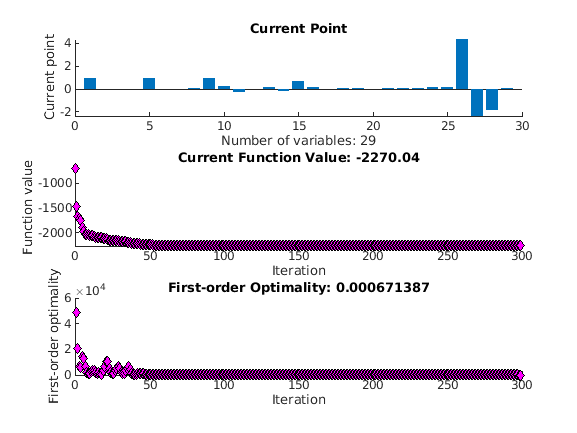


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


Method: Maximum likelihood (fminunc)
Sample size: 324
Logarithmic  likelihood:      2270.04
Akaike   info criterion:     -4482.09
Bayesian info criterion:     -4372.45
       |     Coeff        Std Err      t Stat     Prob  
--------------------------------------------------------
 c(1)  |  0.98903          0.01312    75.40552   0      
 c(2)  | -0.02014          0.01670    -1.20633  0.22770 
 c(3)  |  0.02555          0.04292     0.59523  0.55169 
 c(4)  |  0.00250          0.01572     0.15895  0.87371 
 c(5)  |  0.93378          0.01728    54.04903   0      
 c(6)  |  0.02398          0.03077     0.77932  0.43580 
 c(7)  |  0.00374          0.01042     0.35917  0.71947 
 c(8)  |  0.05828          0.01211     4.81329  0.00000 
 c(9)  |  0.92883          0.02534    36.66087   0      
 c(10) |  0.25785          0.00925    27.86503   0      
 c(11) | -0.24548          0.01664   -14.74876   0      
 c(12) |  0.00352          0.04479     0.07848  0.93745 
 c(13) |  0.20475          0.00640

SSMmod = State-space model type: ssm

State vector length: 3
Observation vector length: 10
State disturbance vector length: 3
Observation innovation vector length: 10
Sample size supported by model: Unlimited

State variables: x1, x2,...
State disturbances: u1, u2,...
Observation series: y1, y2,...
Observation innovations: e1, e2,...

State equations:
x1(t) = (0.99)x1(t-1) + (2.50e-03)x2(t-1) + (3.74e-03)x3(t-1) + (0.26)u1(t)
x2(t) = -(0.02)x1(t-1) + (0.93)x2(t-1) + (0.06)x3(t-1) - (0.25)u1(t) + (0.20)u2(t)
x3(t) = (0.03)x1(t-1) + (0.02)x2(t-1) + (0.93)x3(t-1) + (3.52e-03)u1(t) - (0.14)u2(t)
        + (0.70)u3(t)

Observation equations:
y1(t) = x1(t) + (0.93)x2(t) + (0.06)x3(t) + (0.14)e1(t)
y2(t) = x1(t) + (0.87)x2(t) + (0.11)x3(t) - (6.19e-08)e2(t)
y3(t) = x1(t) + (0.77)x2(t) + (0.19)x3(t) + (0.07)e3(t)
y4(t) = x1(t) + (0.61)x2(t) + (0.27)x3(t) + (0.06)e4(t)
y5(t) = x1(t) + (0.49)x2(t) + (0.30)x3(t) - (4.75e-09)e5(t)
y6(t) = x1(t) + (0.34)x2(t) + (0.28)x

params =     0.9890
   -0.0201
    0.0255
    0.0025
    0.9338
    0.0240
    0.0037
    0.0583
    0.9288
    0.2578


% create the options for the optimization solver
% MaxFunEvals: maximum number of times the routine evaluates the objective function, 
% each time with the updated parameter estimates.
% fminunc: maximum likelihood 
% maximum number of function evaluations = 30,000
% MaxIter: maximum number of iterations are the iterations of the fminunc function 
% itself. 
% tolerance is a threshold which, if crossed, stops the iterations of a solver.
% TolX: lower bound on the step size
% If the fminunc solver attempts to take a step that is smaller than TolX, 
% the iterations end. 
% TolFun: lower bound on the change in the value of the objective function during 
% a step. 
% PlotFcn: plot various measures of progress during the execution of a solver. 

options = optimoptions('fminunc','MaxFunEvals',30000,'algorithm','quasi-newton', ...
    'TolFun' ,1e-9,'TolX',1e-9,'MaxIter',1100,'Display','off',...
    'PlotFcn',{@optimplotx,@optimplotfval,@optimplotfirstorderopt});

% "estimate" function estimates the SSM model ("model") by the Kalman filter
% SSMmod stores the state-space equation, observation equation, 
% means and the covariance matrix of the initial states
% params: 29-by-1 vector of the updated parameters from SSM
% treat the multivariate series as "univariate": sequential filtering
% estimate the asymptotic covariance by taking the outer product of
% gradients (OPG)

[SSMmod,params] = estimate(model,yields,param0,'Display','full', ...
    'options',options,'Univariate',true);


 % Obtain the estimated lambda or decay rate  
lambda = params(end); 

 % Obtain the estimated factor means
mu = params(end-3:end-1)';  

## Contrasting the Estimated Parameters

Below I have contrasted the results yielded from the two-step and SSM methods to analyze the extent of similarities in the results from the aforementioned techniques. Besides, the juxtaposition informs how apt is the use of the two-step approach in establishing the initial parameter values needed to estimate the state-space model. 

First, I have compared the $AR(1)$ coefficient matrix from the VAR model with the state transition matrix $A$ of the SSM model. 

% cellfun: applies the function "disp" to the contents of each cell of cell
% array "display_vars"
% then cellfun concatenates the outputs from "disp" into the output array
% The input argument "disp" is a function handle to a function

disp_ssmA = {"SSM State Transition Matrix (A):";...
    "--------------------------------";...
    SSMmod.A};
cellfun(@disp,disp_ssmA)

SSM State Transition Matrix (A):
--------------------------------
    0.9890    0.0025    0.0037
   -0.0201    0.9338    0.0583
    0.0255    0.0240    0.9288





disp_varA = {"Two-Step State Transition Matrix (A) from VAR(1):";...
    "--------------------------------";...
    VARmod.AR{1}}; 
cellfun(@disp,disp_varA)

Two-Step State Transition Matrix (A) from VAR(1):
--------------------------------
    0.9961    0.0093   -0.0043
   -0.0274    0.9130    0.0631
    0.0334    0.0246    0.9418





disp_bvarA = {"Two-Step State Transition Matrix (A) from BVAR(1):";...
    "--------------------------------";...
    BVARmod.AR{1}}; 
cellfun(@disp,disp_bvarA)

Two-Step State Transition Matrix (A) from BVAR(1):
--------------------------------
    0.9785    0.0004    0.0033
   -0.0325    0.8951    0.0704
    0.0382    0.0326    0.9330



The matrix A from the one-step Kallman filter approach:


$$A_{1-\textrm{step}} =\left\lbrack \begin{array}{ccc}
0\ldotp 9890 & 0\ldotp 0025 & 0\ldotp 0037\\
-0\ldotp 0201 & 0\ldotp 9338 & 0\ldotp 0583\\
0\ldotp 0255 & 0\ldotp 0240 & 0\ldotp 9288
\end{array}\right\rbrack$$


For comparison, I have displayed the two coefficient matrices side-by-side:


$${A_1^{2-\textrm{step}} =\left\lbrack \begin{array}{ccc}
0\ldotp 9961 & 0\ldotp 0093 & -0\ldotp 0043\\
-0\ldotp 0274 & 0\ldotp 913 & 0\ldotp 0631\\
0\ldotp 0334 & 0\ldotp 0246 & 0\ldotp 9418
\end{array}\right\rbrack ,{\;A}_{1-\textrm{step}} =\left\lbrack \begin{array}{ccc}
0\ldotp 9890 & 0\ldotp 0025 & 0\ldotp 0037\\
-0\ldotp 0201 & 0\ldotp 9338 & 0\ldotp 0583\\
0\ldotp 0255 & 0\ldotp 0240 & 0\ldotp 9288
\end{array}\right\rbrack \;}$$


Mostly, the results are in agreement. Notably, the large positive diagonal elements of the SSM matrix and the two-step transition matrices $A$ connote high level of persistent dynamics prevalent in each latent factor. Simultaneously, the very low values of othe off-diagonal elements conveys weak covariance between the factors. 

Secondly, I compared the covariance matrix of the innovation $Q = BB'$ from the state disturbance loading matrix $B$ with the covariance matrix of the innovations from $VAR(1)$ model. The results from both methods are very similar, and the volatility in the state transition shock or the estimated variance (main diagonal elements) of the curvature is the highest, followed by that of slope and curvature, respectively. 

disp_ssmB = {"SSM State Error Loading Matrix (B):";...
    "-----------------------------------------";...
    SSMmod.B};
cellfun(@disp,disp_ssmB)

SSM State Error Loading Matrix (B):
-----------------------------------------
    0.2578         0         0
   -0.2455    0.2047         0
    0.0035   -0.1399    0.6951



disp_ssmQ = {"SSM State Disturbance Covariance Matrix (Q = BB''):";...
    "--------------------------------------------------";...
    SSMmod.B * SSMmod.B'};
cellfun(@disp,disp_ssmQ)

SSM State Disturbance Covariance Matrix (Q = BB''):
--------------------------------------------------
    0.0665   -0.0633    0.0009
   -0.0633    0.1022   -0.0295
    0.0009   -0.0295    0.5028





disp_varQ = {"Two-Step State Disturbance Covariance Matrix (Q) from VAR(1):";...
    "-------------------------------------------------";...
    VARmod.Covariance};
cellfun(@disp,disp_varQ)

Two-Step State Disturbance Covariance Matrix (Q) from VAR(1):
-------------------------------------------------
    0.0598   -0.0604    0.0199
   -0.0604    0.1027   -0.0495
    0.0199   -0.0495    0.4678



disp_bvarQ = {"Two-Step State Disturbance Covariance Matrix (Q) from BVAR(1):";...
    "-------------------------------------------------";...
    BVARmod.Covariance};
cellfun(@disp,disp_bvarQ)

Two-Step State Disturbance Covariance Matrix (Q) from BVAR(1):
-------------------------------------------------
    0.0755   -0.0595    0.0204
   -0.0595    0.1131   -0.0458
    0.0204   -0.0458    0.4698



The matrix $\Sigma_{\eta }$ from the one-step Kalman filter approach:


$$\Sigma_{\eta }^{1-\textrm{step}} =\left\lbrack \begin{array}{ccc}
0\ldotp 0665 & -0\ldotp 0633 & 0\ldotp 0009\\
-0\ldotp 0633 & 0\ldotp 1022 & -0\ldotp 0295\\
0\ldotp 0009 & -0\ldotp 0295 & 0\ldotp 5028
\end{array}\right\rbrack$$


For comparison, I have displayed the variance-covariance matrix of the innovations from VAR(1) with those from the one-step Kalman filter side-by-side:


$$\Sigma_{\eta }^{2-\textrm{step}} =\left\lbrack \begin{array}{ccc}
0\ldotp 0598 & -0\ldotp 0604 & 0\ldotp 0199\\
-0\ldotp 0604 & 0\ldotp 1027 & -0\ldotp 0495\\
0\ldotp 0199 & -0\ldotp 0495 & 0\ldotp 4678
\end{array}\right\rbrack ,\;\;\Sigma_{\eta }^{1-\textrm{step}} =\left\lbrack \begin{array}{ccc}
0\ldotp 0665 & -0\ldotp 0633 & 0\ldotp 0009\\
-0\ldotp 0633 & 0\ldotp 1022 & -0\ldotp 0295\\
0\ldotp 0009 & -0\ldotp 0295 & 0\ldotp 5028
\end{array}\right\rbrack \;$$


The lower triangular matrix B is:


$$Z=\left\lbrack \begin{array}{ccc}
0\ldotp 2578 & 0 & 0\\
-0\ldotp 2455 & 0\ldotp 2047 & 0\\
0\ldotp 0035 & -0\ldotp 1399 & 0\ldotp 6951
\end{array}\right\rbrack$$


Finally, I have estimated means of the level, slope and curvature factors  calculated in both approaches. The average values are very close to each other in both the methods, albeit the mean of curvature is slightly smaller in the two-step approach $\left(-2\ldotp 491\right)$as opposed to that of SSM $\left(-1\ldotp 872\right)\ldotp$

disp_ssm_fmean = {"SSM Factor Means:";...
    "-----------------";...
    mu};
cellfun(@disp,disp_ssm_fmean)

SSM Factor Means:
-----------------
    4.3549   -2.3513   -1.8720



disp_2step_fmean = {"Two-Step Factor Means:";...
    "----------------------";...
    mu0'};
cellfun(@disp,disp_2step_fmean)

Two-Step Factor Means:
----------------------
    4.7137   -2.2325   -2.4910



## Contrasting the Derived Factors

The variables primarily of interest in projecting the ex-ante path of the yield curve are the Diebold-Li model's unobserved factors . While maximum likelihood estimates the unknown parameters,filtering, smoothing and forecasting measure the unobserved states. I have analyzed the states inferred from each approach. The coefficients from the OLS regression in the first step are the latent states (factors). Kalman smoother extracts optimal values of the three factors.The the `smooth` function in the SSM model carries out the Kalman smoothing process wherein the smoothed states for all $t = 1,2,...T$ are:


$$E[x_t|y_T,...,y_1]$$


However, before invoking the `smooth` function, during the estimation, the SSM formulation considers the offset adjustments made to the yields observed. In particular, the parameter mapping function deflates the original yields while estimating. Further, rather than working with the original yields, it works with the offset-adjusted yields $:y'_t = y_t - \Lambda\mu$. The SSM model estimated is oblivious of the adjusted yields as only the mapping function contains the adjustments. Thereby, the other SSM functions such as `smooth`, `filter`, `simulate`, and `forecast `must take into consideration the regression components related to the measurement equation's predictors.  Consequently, I have demeaned the original yields before calling the `smooth` function to ascertain the estimated states. To deflate, I subtracted the intercept corresponding to the estimated offset, $C\mu = \Lambda\mu$, as it counteracts the offset adjustment during the estimation process. Yet, the inferred states are associated with the demeaned, although the actual states (the level, slope, and curvature factors) are variables of interest, rather than their corresponding offset-adjusted values. Therefore, I have readjusted the demeaned states after smoothing by adding the estimated mean, $\mu$, to the factors.

intercept = SSMmod.C * mu';

% demeaned the yields  as the SSM functions such as filter,  smooth, forecast, 
% and simulate, assume that observations are already manually demeaned. 
% offset: Truncate vectors by removing or keeping beginning or ending values

% bsxfun: apply element-wise operation to two arrays with implicit expansion enabled
% subtract the intercept from the yields to get the demeaned yields
def_yields = bsxfun(@minus,yields,intercept');

% returns smoothed states "def_states" by performing backward recursion on
% the fully specified state-space model "SSMmod"
% "smooth" applies the standard Kalman filter using "SSMmod" 
% and the responses observed: "def_yields".
def_states = smooth(SSMmod,def_yields); 


% add the estimated means "mu" to the demeaned states (factors)
est_states = bsxfun(@plus,def_states,mu);

After inferring the states, I have separately plotted the latent factors : level, slope and curvature latent  derived from the two-step approach and the state-space model. The long-term factor or level is:

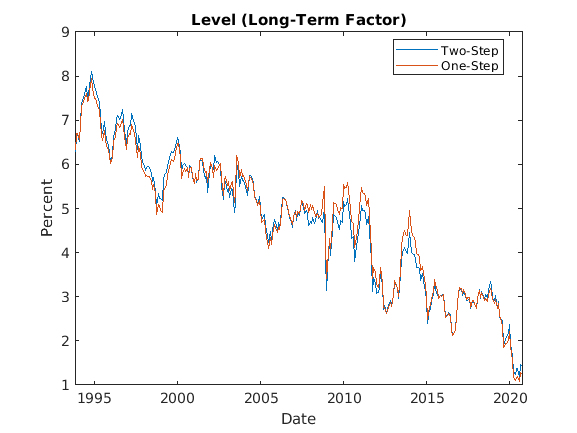

figure
plot(dates, [beta(:,1) est_states(:,1)])
title('Level (Long-Term Factor)')
ylabel('Percent')
xlabel('Date')
legend({'Two-Step','One-Step'},'location','best')

The short-term factor or slope is:

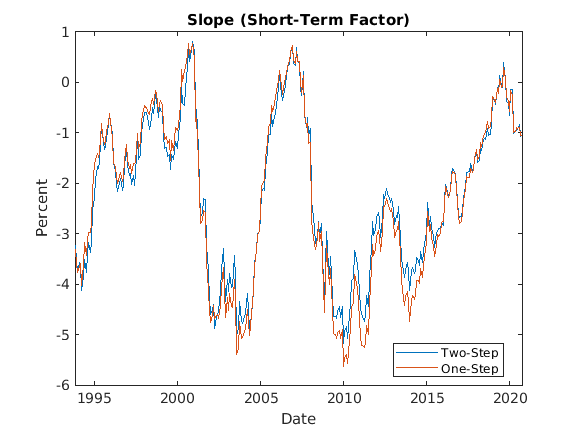

figure
plot(dates, [beta(:,2) est_states(:,2)])
title('Slope (Short-Term Factor)')
ylabel('Percent')
xlabel('Date')
legend({'Two-Step','One-Step '},'location','best')

The medium-term factor or curvature is:

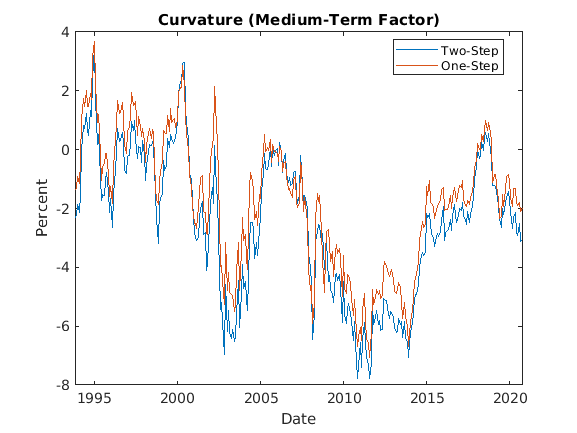

figure
plot(dates, [beta(:,3) est_states(:,3)])
title('Curvature (Medium-Term Factor)')
ylabel('Percent')
xlabel('Date')
legend({'Two-Step','One-Step '},'location','best')

From the separate graphs of all the three factors, the level factor shows considerable persistance as the trajectory indicates a long-term downward trend. Alternatively, the slope and curvature factors are more volatile as they fluctuate from trough to crests, taking in both negative and positive values. Linked with the curvature factor, the estimated decay rate parameter $\lambda$ is $0.0456$. Unlike the constant decay rate applied in the two-step approach where $\lambda$ is  $0.0609,$ the decay rate parameter estimated from the one-step method  is lower.

display_vars = {"SSM Rate of Decay (lambda):";...
    "------------------------";...
    lambda};

% apply the function "disp" to each cell of cell array "display_var"
% "disp": displays the value of lamda
cellfun(@disp,display_vars)

SSM Rate of Decay (lambda):
------------------------
    0.0456



$\lambda$ determines the time to maturity at which the loading on the curvature is maximized. I have plotted the loading on curvature linked to each value of $\lambda$. Setting $\lambda$ arbitrarity to $0.0609$ maximizes the loading on the curvature at precisely $28\ldotp 58$ months. As opposed to the two-step approach, when $\lambda$ is estimated to be $0.0456$ in the one-step approach, the curvature on loading is maximized a decade later in exactly $39\ldotp 5$ months. We can attribute the interpretation of curvature as a medium-term factor to the hump-shape (concave looking) curves as a function of the time to maturity for both values of $\lambda$.  

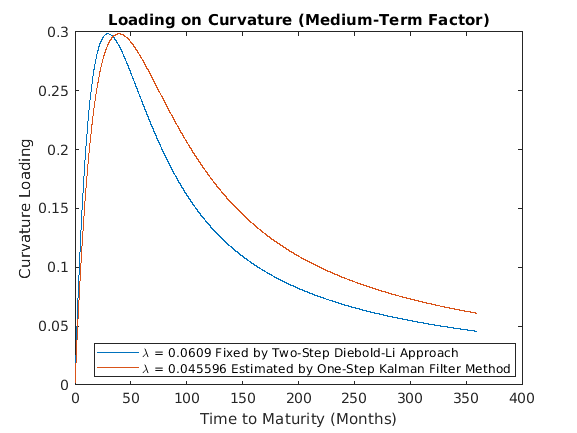

% max(ttm) = 360 and 360*12 = 4320
tau = 0:(1/12):max(ttm);    % time to maturity (months)

% store 2 lambda values from the two-step and SSM approaches
decay = [lambda0 lambda]; 

% numel(tau): number of elements in "tau" = 4321
% zeros(4321, 2) = 4321-by-2 matrix of 0s
loading = zeros(numel(tau), 2);

% loadings on the medium-term factor: curvature
for i = 1:numel(tau)
    loading(i,:) = ((1-exp(-decay*tau(i)))./(decay*tau(i))-exp(-decay*tau(i))); 
end

figure
plot(tau,loading)
title('Loading on Curvature (Medium-Term Factor)')
xlabel('Time to Maturity (Months)')
ylabel('Curvature Loading')
legend({'\lambda = 0.0609 Fixed by Two-Step Diebold-Li Approach ', ...
    ['\lambda = ' num2str(lambda) ' Estimated by One-Step Kalman Filter Method'],}, ...
    'location','best')

Albeit differences in the path of the curvature's loading from both the methods, which are promiment after the loadings reach the apex, the factors derived from both methods are reasonably similar. I think I would prefer to use the one-step SSM wherein I simultaneously estimated all the parameters. A caveat of the two-step approach is that the second step does not take into account the parameters estimated and the uncertainity associated with extracting signals in the first step.  

Now, I have contrasted the standard deviations and means of the residuals of the measurement equations from the two methods, and expressed the results in basis points (bps). In the SSM framework, the state measurement sensitivity matrix $C$ is equivalent to the factor loadings matrix  $\Lambda.$ 

% residuals from the measurement equation
resid_SSM = yields - est_states*SSMmod.C';

% residuals from the two-step approach
resid_2step = yields - beta*X';

% Average and standard deviation of the residuals from the
% One-step Kalman filter approach
resid_avg_ssm = 100*mean(resid_SSM)';
resid_sd_ssm = 100*std(resid_SSM)';

% Average and standard deviation of the residuals from the
% Two-step Diebold-Li approach
resid_avg_2step = 100*mean(resid_2step)';
resid_sd_2step = 100*std(resid_2step)';

display_vars = {"  -------------------------------------------------";...
    "              One-Step             Two-Step";...
    "            -------------------  ------------------";...
    "                       Standard            Standard";...
    "  Maturity    Mean    Deviation    Mean   Deviation";...
    "  (Months)   (bps)      (bps)     (bps)     (bps)  ";...
    "  --------  --------  ---------  -------  ---------";...
    [ttm resid_avg_ssm resid_sd_ssm resid_avg_2step resid_sd_2step]};

cellfun(@disp,display_vars)

  -------------------------------------------------
              One-Step             Two-Step
            -------------------  ------------------
                       Standard            Standard
  Maturity    Mean    Deviation    Mean   Deviation
  (Months)   (bps)      (bps)     (bps)     (bps)  
  --------  --------  ---------  -------  ---------
    3.0000   -7.9165   11.8059   -8.2772    6.9310
    6.0000    0.0000    0.0000    2.8505    4.3342
   12.0000    1.6919    7.2086    7.3354    8.1979
   24.0000    3.2513    5.1182    7.1949    5.7332
   36.0000    0.0000    0.0000   -0.3532    3.5134
   60.0000   -1.3002    6.1814   -7.6432    6.5867
   84.0000    1.2382    5.8963   -6.6773    7.8875
  120.0000   -2.0432    3.8820   -8.9523    5.5131
  240.0000   12.9364   15.1194   10.1659    8.7315
  360.0000    5.4692   17.2032    4.3565   10.8041




disp_sumstat_beta = {"Summary Statistics of the Latent Variables from DNS:";...
    "----------------------------------";...
    tab_beta};
cellfun(@disp,disp_sumstat_beta)

Summary Statistics of the Latent Variables from DNS:
----------------------------------
                Min       Mean        Max      Std_dev
              _______    _______    _______    _______

    beta 1     1.1602     4.7137     8.1034    1.5517 
    beta 2    -5.1804    -2.2325    0.81551    1.5339 
    beta 3    -7.7825     -2.491     3.5225    2.4178 




% Average value of standard deviation from SSM
avg_sd_ssm = mean(resid_sd_ssm);

% Average value of standard deviation from the two-step approach
avg_sd_2step = mean(resid_sd_2step);

disp_avg_ssm = {"Average value of standard deviation from One-Step:";...
    "----------------------------------";...
    avg_sd_ssm};
cellfun(@disp,disp_avg_ssm)

Average value of standard deviation from One-Step:
----------------------------------
    7.2415




disp_avg_2step = {"Average value of standard deviation from Two-Step:";...
    "----------------------------------";...
    avg_sd_2step};
cellfun(@disp,disp_avg_2step)

Average value of standard deviation from Two-Step:
----------------------------------
    6.8233



Though SSM fits better for maturities ranging from 6 months to 10 years, the deviation is extrmeley high for the shortest (3 month) and long term maturities (20 and 30 years). These extreme values in standard deviation push the average value of the standard deviation of the residuals from SSM larger $\left(7\ldotp 2415\right),$than that from the two-step approach $\left(6\ldotp 8233\right)\ldotp$ So we can reckon that the the yield curve fitted with the constant $\lambda$ from the  two-step approach generates more accurate, and hence, is preferable to the SSM.

## Monte Carlo Simulations and Forecasts

The SSM function enables us to simulate the path of the yield curve by Mone Carlo method and and construct minimum mean square error (MMSE) forecasts. As the Diebold-Li model is founded upon the non-linear combination of the unobserved estimated factors, forecasting the factors is tantamount to forecasting the yield curve. Yet, because I estimated the one-step method  after making the offset adjustment, so the estimates are based on the demeaned yields. Therefore, I have applied the `forecast` function on the demeaned yields to calculate the MMSE foecasts of the demeaned yields 12 months into the future. Then, I added the estimated offset $C\mu$ to the demeaned yields to obtain the  ex-ante foreasts of actual yields and stored it in `forecast_yields.` Since the forecast horizon is set to 12, then for each of the 10 different maturities, `forecast_yields `is a$\;\left(12\times 10\right)$  matrix of forecasts for each time to maturity. 

horizon = 12; % forecast horizon (months)

% call the forecast function on the demeaned yields to compute the MMSE forecasts
[forecast_def_yields,mse] = forecast(SSMmod,horizon,def_yields);

% add the estimated offset C*mu to the demeaned yields: forecasts of yields
forecast_yields = bsxfun(@plus,forecast_def_yields,intercept');

After enumerating the deterministic MMSE forecasts, I have approximated the same results using Mone Carlo simulation. To ensure that the simulation takes into account the latest information, I initialized covariance matrix and the mean vector of the initial states (factors) from the estimated one-step approach. Thereby, I procured the smoothed states via backward recursion.

% call the smooth function to acquire the smoothed states
% backward recursion  yields the smoothed states
[~,~,results] = smooth(SSMmod,def_yields);  

% initialize the mean vector at the end of the historical dataset
SSMmod.Mean0 = results(end).SmoothedStates;     
cov0 = results(end).SmoothedStatesCov;

% initialize the covariance matrix 
SSMmod.Cov0 = (cov0 + cov0')/2;                 

Thereafter, I computed the ex-ante yield curve by Monte Carlo simulation $100,000$ times. Each simulation projects the yields of ten different maturities, twelve months into the future, creating a $100,000\times 12\times 10$ dimension of `sim_def_yields. `As before, I have added the factor offsets from the demeaned yields to get the unnormalized yields.  

rng('default') % rng: random number generator

% repeat the simulation 100,000 times
% each path is the ex-ante (simulated) yield curve of the future
nPaths = 100000;
% 100,000 sims of 10 demeaned yields (columns), 12 months in the future (rows)
sim_def_yields = simulate(SSMmod, horizon, nPaths);

% add the estimated offset C*mu to the demeaned yields: forecasts of yields
sim_yields = bsxfun(@plus, sim_def_yields, intercept');

Analogous to the MMSE forecasts and standard errors, I caliberated sample standard deviation and mean of the 100,000 trials. I reordered the matrix of simulated yields to calculate the sample means and standard deviations. The matrix encompasses 100,000 rows, 12 columns, and 10 pages.

% sim_yields: matrix of simulated yields: 100,000 rows, 12 columns and 10 pages
sim_yields = permute(sim_yields,[3 1 2]); % re-order for convenience
forecasts = zeros(horizon,numel(ttm));
std_errors = zeros(horizon,numel(ttm));

for i = 1:numel(ttm)
    forecasts(:,i) = mean(sim_yields(:,:,i));
    std_errors(:,i) = std(sim_yields(:,:,i));
end

Visually comparing the projections and standard errors from MMSE and Monte Carlo methods convey idential paths of the yield curve. 

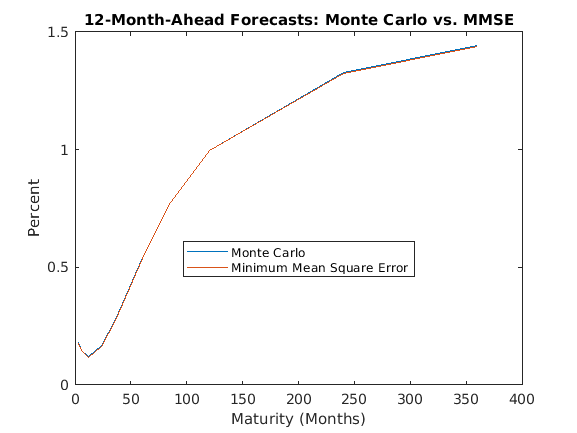

figure
plot(ttm, [forecasts(horizon,:)' forecast_yields(horizon,:)'])
title('12-Month-Ahead Forecasts: Monte Carlo vs. MMSE')
xlabel('Maturity (Months)')
ylabel('Percent')
legend({'Monte Carlo','Minimum Mean Square Error'},'location','best')

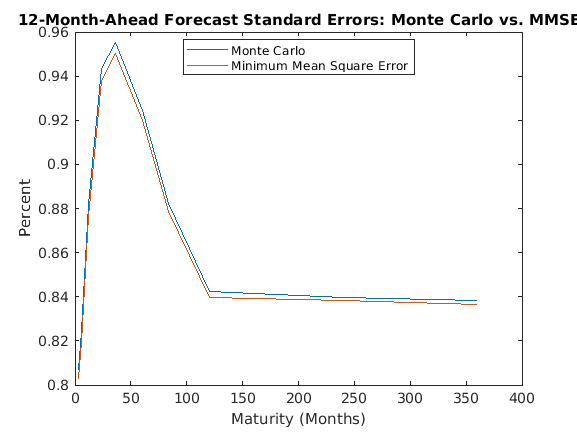


figure
plot(ttm, [std_errors(horizon,:)' sqrt(mse(horizon,:))'])
title('12-Month-Ahead Forecast Standard Errors: Monte Carlo vs. MMSE')
xlabel('Maturity (Months)')
ylabel('Percent')
legend({'Monte Carlo','Minimum Mean Square Error'},'location','best')

Beyond the mean and standard errors, Monte Carlo simulations provide insight into the distribution of yields. As a corollary, we can gauge the distribution of other macroeconomic variables that depend on the yield curve. Next, the plots represent the distibution of the simulated 1 year yield at one, six, and twelve months into the future. 

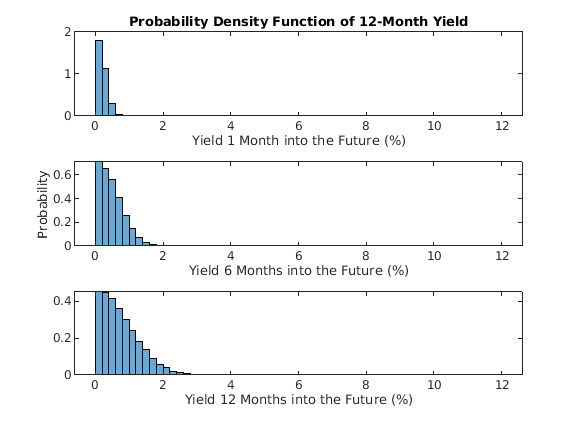

index12 = find(ttm == 12);  % page index of 12-month yield
bins = 0:0.2:12;

% 12-month yield forecasted 1 month into the future
figure
subplot(3,1,1)
histogram(sim_yields(:,1,index12), bins, 'Normalization', 'pdf')
title('Probability Density Function of 12-Month Yield')
xlabel('Yield 1 Month into the Future (%)')

% 12-month yield forecasted 6 months into the future
subplot(3,1,2)
histogram(sim_yields(:,6,index12), bins, 'Normalization', 'pdf')
xlabel('Yield 6 Months into the Future (%)')
ylabel('Probability')

% 12-month yield forecasted 12 months into the future
subplot(3,1,3)
histogram(sim_yields(:,12,index12), bins, 'Normalization', 'pdf')
xlabel('Yield 12 Months into the Future (%)')

## Summary

I have  formulated the Diebold-Li’s two-step approach into a state-space representation by defining the state and measurement equations, and estimated the parameters via the Kalman filter. The One-Step  is a stochastic, discrete-time model with two equations: state and measurement equations. The state equation characterizes the transition of the latent (unobserved) states, and the observation equation connects the states to the observed data on yield curve in this analysis. It expresses how we can indirectly caliberate the latent process at each time period. From the time-series of various yield curves, I inferred the three latent states or factors $-$ level, slope, and curvature, that drive the evolution of the term structure of interest rates. Then, applying the functionalities of the One-Step , I estimated the parameters using the Kalman filter, smoothed, forecasted and constructed Monte Carlo simulations.

## **References**

Diebold, F. X., & Li, C. (2006). Forecasting the term structure of government bond yields. *Journal of Econometrics,* *130*(2), 337-364. doi:10.1016/j.jeconom.2005.03.005

Diebold, F. X., Rudebusch, G. D., & Aruoba, S. B. (2006). The macroeconomy and the yield curve: A dynamic latent factor approach. *Journal of Econometrics,* *131*(1-2), 309-338. doi:10.1016/j.jeconom.2005.01.011

Diebold, Francis X., and Glenn D. Rudebusch. Yield Curve Modeling and Forecasting: The Dynamic Nelson-Siegel Approach. *Princeton University Press,* 2013. 

[https://www.mathworks.com/help/fininst/fitting-the-diebold-li-model_example-ex10300997.html](https://www.mathworks.com/help/fininst/fitting-the-diebold-li-model_example-ex10300997.html)

[https://www.mathworks.com/help/econ/using-the-kalman-filter-to-estimate-and-forecast-the-diebold-li-model.html](https://www.mathworks.com/help/econ/using-the-kalman-filter-to-estimate-and-forecast-the-diebold-li-model.html)**

*In particular, I acknowledge the signficant help taken from the last website, but I have made several additions and modifications. The website served as a useful guide in estimating the state space models for the first time.